Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 6a -- DFS of data

%{
    This will be a script that will solve the problems in Assignment 6a. 

    Sam Kramer
    Feb 15th, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

    As a follow-up to assignment 6, a signal (sig1) is shown. It contains random content and a harmonic component at 35.5 Hz. Since we can only calculate integer multiples of w0 from the Fourier series, estimate the amplitude of the component using 35Hz and 36Hz. You might want to try 34Hz and 37Hz as well. What do you get if you try to extract 35.5 Hz directly. 

    Explain the results.

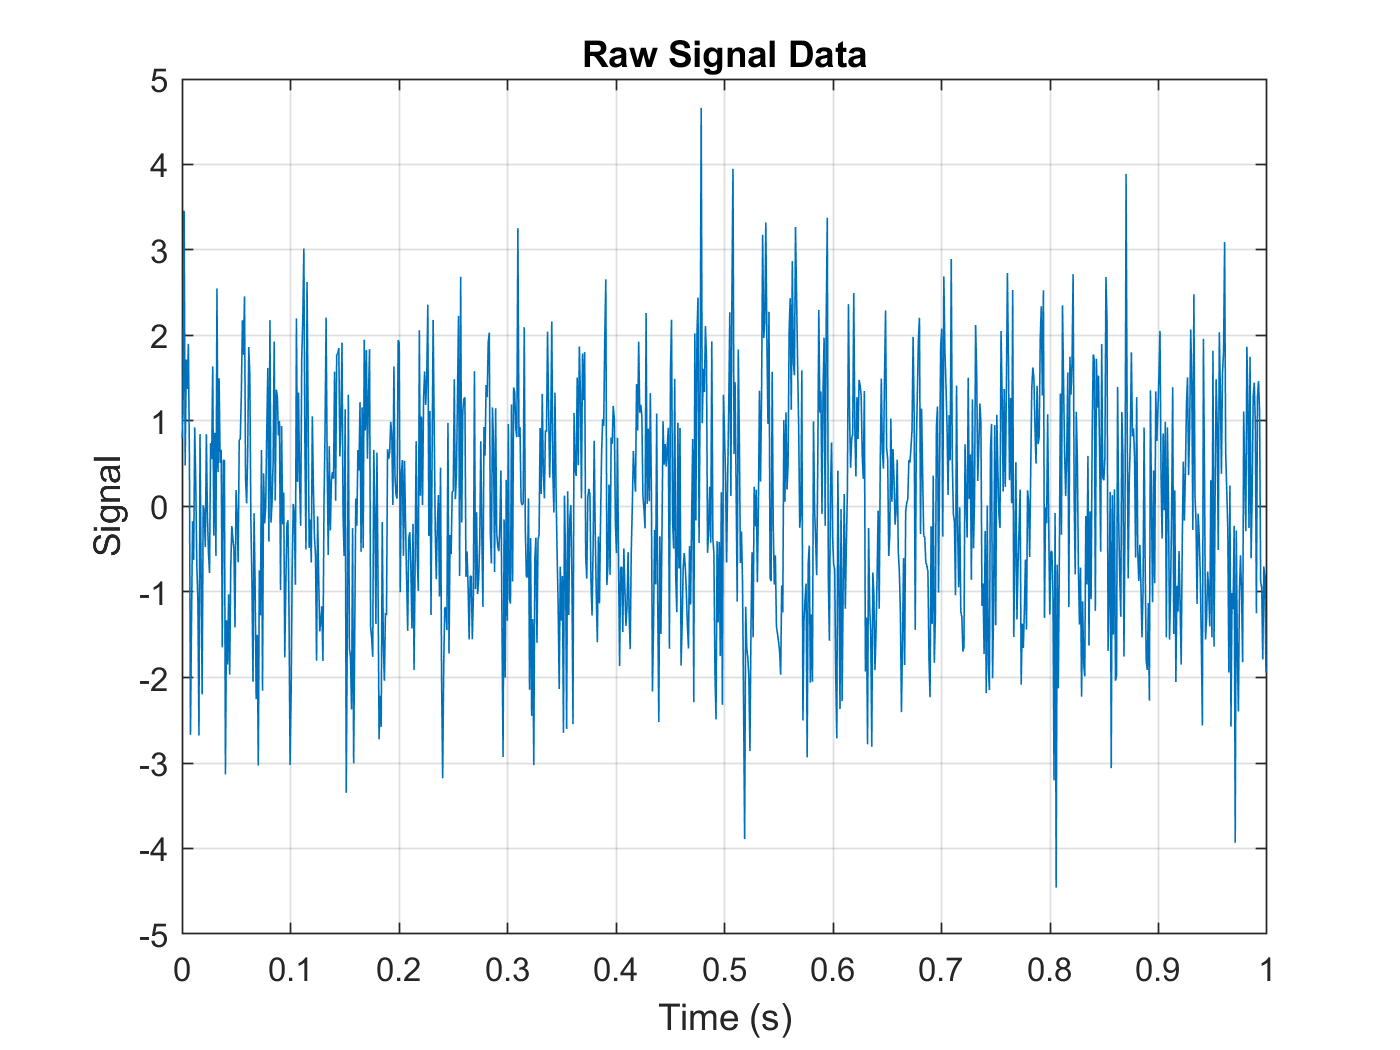

% --Parameters
    fs = 1024;          % Sample Frequency
    magnitude = [];     % magnitude solution Vector
    phase = [];         % Phase solution vector
    magnitude2 = [];    % Ca solution Vector
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%% Initial Data Plotting %%%%%%%%%%%%%%%%%%%%%%%%%
    
% --Load in Data
    a6data = load('6adata.mat');
    
    % --Reformat data
        signal = a6data.sig1;           % Define the signal
        T = a6data.t;                   % Define the period
        N = length(signal);             % Number of signal samples
        t = 1/N;                        % Time step
        w0 = 1:length(signal);          % Frequency vector 
    
% --Plot data
    plot(T,signal);
        title('Raw Signal Data')
        xlabel('Time (s)')
        ylabel('Signal')
        hold on;
        grid on;

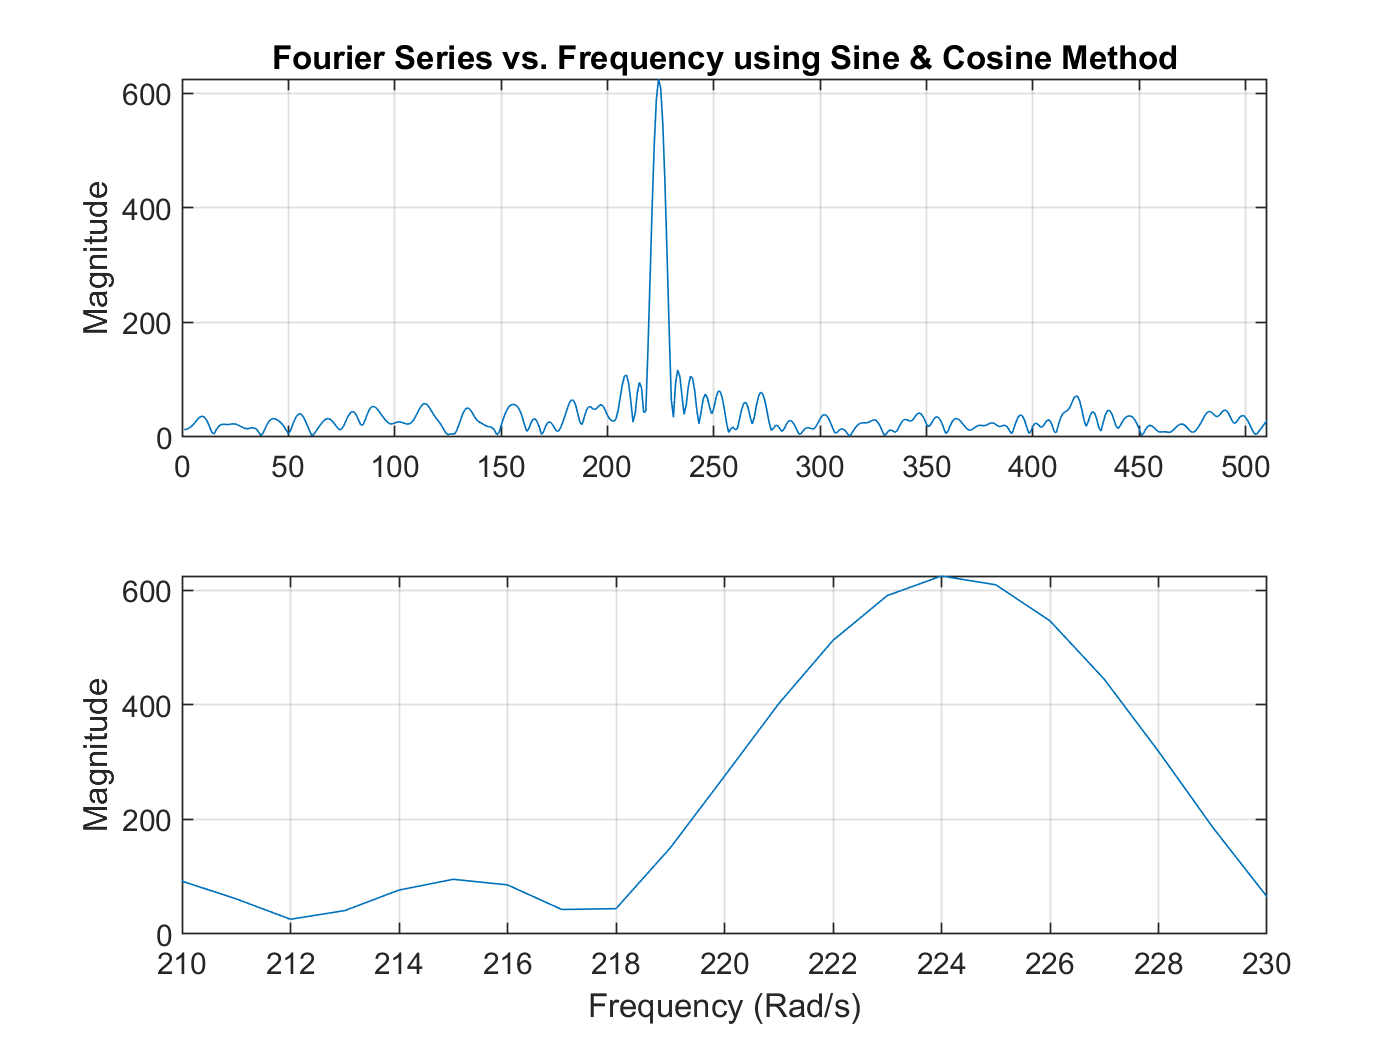

      
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Fourier Series %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
% --Calculate Fourier Series
    for n = 0:(N/2) - 1
        
        % --Create cosine and sine vectors
            Cosine_n = cos(n*w0*t)';
            Sine_n = sin(n*w0*t)';
            
        % --Summation of data
            An = mean(signal * Cosine_n);
            Bn = mean(signal * Sine_n);
        
        % --Calculate magnitude
            Cn = sqrt(An.^2 + Bn.^2);
            phi = atan(Bn / An);
            
        % --Save Values
            magnitude = [magnitude Cn];
            phase = [phase phi];
            
    end
    
% --reformat frequency
    freq = w0 ./ 1;
    freq = freq(1:(N/2));
    phase = phase * pi/2;
    freqHz = freq./(2*pi);
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Plot %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% --Plot Magnitude vs. Frequency
    figure(3)
    subplot(2,1,1)
    plot(freq,magnitude);
        grid on
        hold on
        xlim([0 510])
        xline(0,'--')
        ylabel('Magnitude')
        title('Fourier Series vs. Frequency using Sine & Cosine Method')
        
        
    subplot(2,1,2)
    plot(freq, magnitude)
        grid on
        hold on
        xlim([210 230])
        xlabel('Frequency (Rad/s)')
        ylabel('Magnitude')

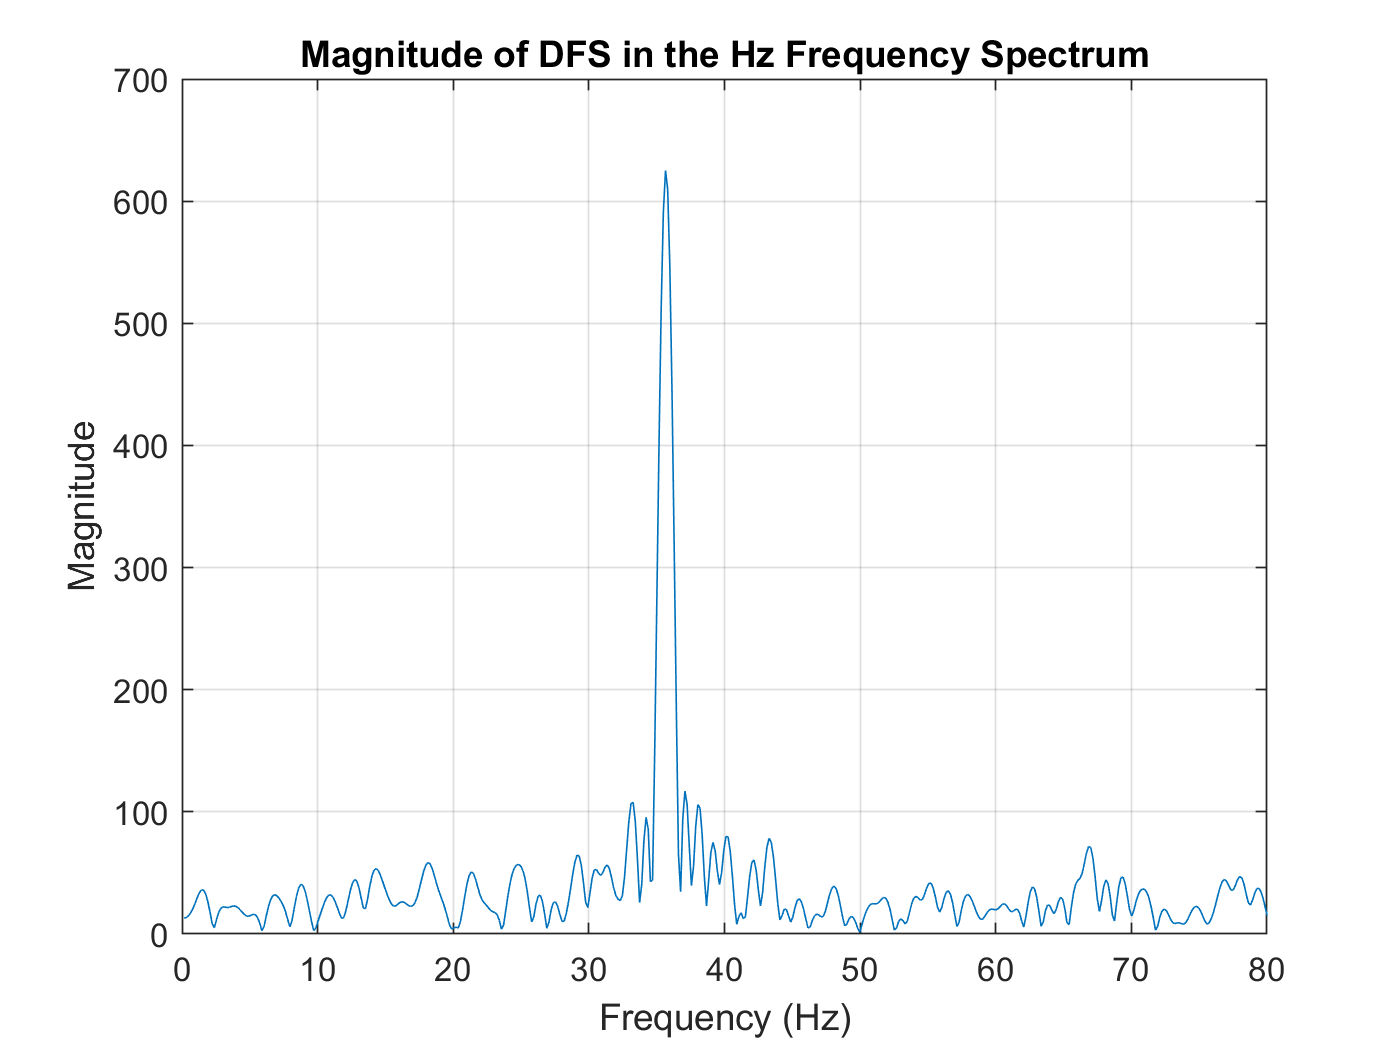

   
    figure(4)
    plot(freqHz, magnitude)
        grid on
        hold on
        ylabel('Magnitude')
        xlabel('Frequency (Hz)')
        xlim([0 80])
        title('Magnitude of DFS in the Hz Frequency Spectrum')

###  Analysis

    For this specific data set, we can find the fourier series to the system and we can see that the specific peak in the system reaches its maximum at 224 rad/s. The peak at the value is 625. If we transform the data into Hz, then we can see that the peak happens at 36.6 Hz. This is only slightly off from the value of 35.5, however, we will not be able to measure the peak at 35.5 Hz because we would need to have a value calculated at a non-integer multiple of the frequency in rad/s. If we look at the rad/s graph, the samples are located at all integer values, this is because of the way that the discrete fourier series works. There is a wide curve in the data, because there is leakage on either side of the peak because we are unable to calculate the exact value of the frequencies. In fact, if we try and calculate the values in non integer values we get an error because we have vector length errors. 